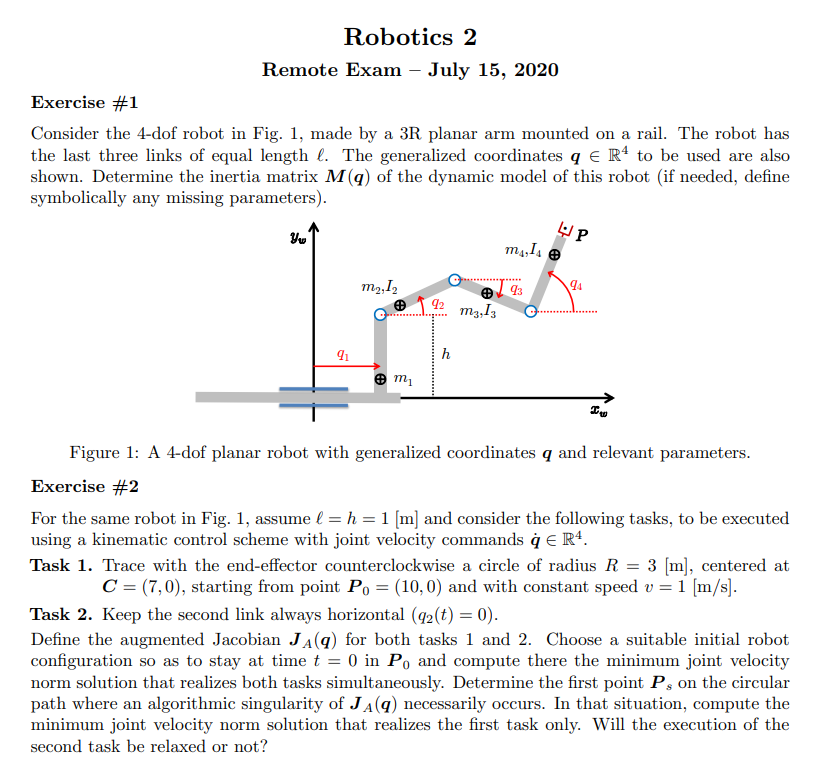

syms q1 q2 q3 q4 q_dot_1 q_dot_2 q_dot_3 q_dot_4 I_2 I_3 I_4 real
syms m_1 m_2 m_3 m_4 l_1 l_2 l_3 d_1 d_2 d_3 d_4 h g0 l positive

T1 = 0.5*m_1*q_dot_1^2

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


x2 = q1+d_2*cos(q2);
y2 = h+d_2*sin(q2);

vx2 = diff(x2,q1)*q_dot_1+diff(x2,q2)*q_dot_2+diff(x2,q3)*q_dot_3+diff(x2,q4)*q_dot_4;
vy2 = diff(y2,q1)*q_dot_1+diff(y2,q2)*q_dot_2+diff(y2,q3)*q_dot_3+diff(y2,q4)*q_dot_4;

T2 = 0.5*m_2*[vx2 vy2]*[vx2; vy2;]+0.5*I_2*(q_dot_2)^2

$$T2 = \frac{m_{2}\,{\left({\dot{q}}_{1}-d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}$$


x3 = q1+l_2*cos(q2)+d_3*cos(q3);
y3 = h+l_2*sin(q2)+d_3*sin(q3);

vx3 = diff(x3,q1)*q_dot_1+diff(x3,q2)*q_dot_2+diff(x3,q3)*q_dot_3+diff(x3,q4)*q_dot_4;
vy3 = diff(y3,q1)*q_dot_1+diff(y3,q2)*q_dot_2+diff(y3,q3)*q_dot_3+diff(y3,q4)*q_dot_4;

T3 = 0.5*m_3*[vx3 vy3]*[vx3; vy3;]+0.5*I_3*(q_dot_3)^2

$$T3 = \frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)-{\dot{q}}_{1}+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}$$


x4 = q1+l_2*cos(q2)+l_3*cos(q3)+d_4*cos(q4);
y4 = h+l_2*sin(q2)+l_3*sin(q3)+d_4*sin(q4);

vx4 = diff(x4,q1)*q_dot_1+diff(x4,q2)*q_dot_2+diff(x4,q3)*q_dot_3+diff(x4,q4)*q_dot_4;
vy4 = diff(y4,q1)*q_dot_1+diff(y4,q2)*q_dot_2+diff(y4,q3)*q_dot_3+diff(y4,q4)*q_dot_4;

T4 = 0.5*m_4*[vx4 vy4]*[vx4; vy4;]+0.5*I_4*(q_dot_4)^2

$$T4 = \frac{I_{4}\,{{\dot{q}}_{4}}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{4}\right)+l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)+l_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)-{\dot{q}}_{1}+l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}$$


T = T1+T2+T3+T4

$$T = \begin{array}{l} \frac{m_{2}\,{\left({\dot{q}}_{1}-d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{I_{4}\,{{\dot{q}}_{4}}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)-{\dot{q}}_{1}+\sigma_{1}\right)}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,{\left(d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)+\sigma_{2}\right)}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{4}\right)+\sigma_{2}+l_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{4}\,{\left(d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)-{\dot{q}}_{1}+\sigma_{1}+l_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right) \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);
M14 = diff(diff(T, q_dot_1), q_dot_4);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);
M24 = diff(diff(T, q_dot_2), q_dot_4);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);
M34 = diff(diff(T, q_dot_3), q_dot_4);

M41 = diff(diff(T, q_dot_4), q_dot_1);
M42 = diff(diff(T, q_dot_4), q_dot_2);
M43 = diff(diff(T, q_dot_4), q_dot_3);
M44 = diff(diff(T, q_dot_4), q_dot_4);

M = simplify([M11, M12, M13, M14; M21, M22, M23, M24; M31, M32, M33, M34; M41, M42, M43, M44])

$$M = \begin{array}{l} \left(\begin{array}{cccc} m_{1}+m_{2}+m_{3}+m_{4} & \sigma_{1} & \sigma_{3} & -d_{4}\,m_{4}\,\sin\left(q_{4}\right)\\ \sigma_{1} & I_{2}+{d_{2}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{4} & \sigma_{2} & \sigma_{5}\\ \sigma_{3} & \sigma_{2} & m_{3}\,{d_{3}}^{2}+m_{4}\,{l_{3}}^{2}+I_{3} & \sigma_{4}\\ -d_{4}\,m_{4}\,\sin\left(q_{4}\right) & \sigma_{5} & \sigma_{4} & m_{4}\,{d_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sin\left(q_{2}\right)\,\left(d_{2}\,m_{2}+l_{2}\,m_{3}+l_{2}\,m_{4}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{2}-q_{3}\right)\,\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{3}=-\sin\left(q_{3}\right)\,\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{4}=d_{4}\,l_{3}\,m_{4}\,\cos\left(q_{3}-q_{4}\right)\\ \sigma_{5}=d_{4}\,l_{2}\,m_{4}\,\cos\left(q_{2}-q_{4}\right) \end{array}$$

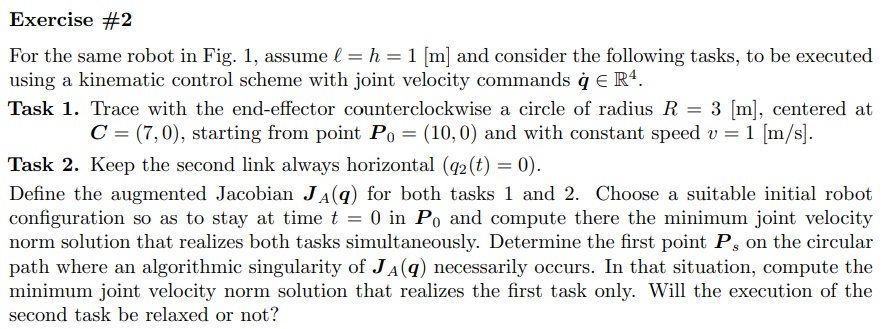

p1 = [q1+l*(cos(q2)+cos(q3)+cos(q4)); h+l*(sin(q2)+sin(q3)+sin(q4));]

$$p1 = \left(\begin{array}{c} q_{1}+l\,\left(\cos\left(q_{2}\right)+\cos\left(q_{3}\right)+\cos\left(q_{4}\right)\right)\\ h+l\,\left(\sin\left(q_{2}\right)+\sin\left(q_{3}\right)+\sin\left(q_{4}\right)\right) \end{array}\right)$$


J1 = jacobian(p1,[q1,q2,q3,q4])

$$J1 = \left(\begin{array}{cccc} 1 & -l\,\sin\left(q_{2}\right) & -l\,\sin\left(q_{3}\right) & -l\,\sin\left(q_{4}\right)\\ 0 & l\,\cos\left(q_{2}\right) & l\,\cos\left(q_{3}\right) & l\,\cos\left(q_{4}\right) \end{array}\right)$$

p2 = [q1+l*(cos(q2));
      h+l*(sin(q2));];

p2_subs = subs(p2,[q2],[0])

$$p2\_subs = \left(\begin{array}{c} l+q_{1}\\ h \end{array}\right)$$

J2 = jacobian(p2_subs,[q1,q2,q3,q4])

$$J2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$